# Copper Solvent Extraction

Pieter Leon van den Berg

22684166

25 April 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Copper solvent extraction

Dynamic model of a copper solvent extraction plant to use for fault detection.

### Setup

clear;
clc;

### Simulation Time

simulation_time = 7*60*60; % [s] Run the model for 700 hours
sampling_time   = 0.01;        % [s] Simulate the process every 30 seconds

## Parameters

### Mass transfer coefficients

K_mass_1 = 1.13;    % [1/s]
K_mass_2 = 0.0186;  % [1/s]
K_mass_3 = 0.672;   % [1/s]
K_mass_4 = 0.398;   % [1/s]

### Equilibrium concentrations

% Extraction
C_org_max = 22.73;  % [g/L]
K_eq_ext  = 88.00;  % [L/g]

% Stripping
C_aq_max  = 94.34;  % [g/L]
K_eq_str  = 2.16;   % [L/g]

### Valve Sizing

% Organic
fLO_max   = 556;    % [L/s]

% Electrolyte
fLE_max   = 390;    % [L/s]

### Mixer volumes

V1 = 1400;          % [L]
V2 = 1400;          % [L]
V3 = 1400;          % [L]  
V4 = 1400;          % [L]

### Settler delays

t1 = 900;           % [s]
t2 = 900;           % [s]
t3 = 900;           % [s]
t4 = 900;           % [s]

## Steady-state Values

### Concentrations

% PLS
cPLS_ss  = 7;               % [g/L]

% Aqueous
C1_aq_ss = 0.007594752;     % [g/L]
C2_aq_ss = 0.006420935;     % [g/L]
C3_aq_ss = 0.033235766;     % [g/L]

% Organic
C1_org_ss = 7.876910289;    % [g/L]
C2_org_ss = 7.919777096;    % [g/L]
C3_org_ss = 14.87991304;    % [g/L]
C4_org_ss = 0.885172472;    % [g/L]

% Electrolyte
cLE_ss   = 35;              % [g/L]
C1_el_ss = 54.95809839;     % [g/L]

### Flowrates

% PLS
fPLSP_ss = 278;    % [L/s]
fPLSS_ss = 278;    % [L/s]

### Valves

vLO_ss   = 0.5;     % [-]
vLE_ss   = 0.5;     % [-]

## Sensor Noise

### Controlled variables

sigma_c_LO   = 0.003;   % [g/L]
sigma_c_RE   = 0.003;   % [g/L]

### Flowrates

sigma_f_PLSP = 0.47;    % [L/s]
sigma_f_PLSS = 0.47;    % [L/s]
sigma_f_LO   = 0.47;    % [L/s]
sigma_f_LE   = 0.33;    % [L/s]

### Concentrations

sigma_c_PLS   = 0.003;   % [g/L]
sigma_c_LE    = 0.003;   % [g/L]
sigma_c_RaffP = 0.003;   % [g/L]
sigma_c_RaffS = 0.003;   % [g/L]
sigma_c_BO    = 0.003;   % [g/L]

## Run the Simulink Model

simulation_results = sim('process_model/copper_solvent_extraction_model_simulink');

## Plot the Simulation Results

### Setup plotting

opengl software

### Plot colours

orange = '#FF9A5B';
blue   = '#06ACE9';

### Setup the time

% Convert the simulation time from seconds to hours
model_time = simulation_results.tout / (60*60);

### Plot the organic concentrations

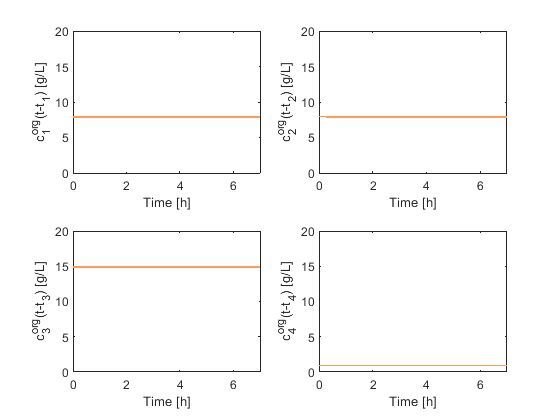

% Create the group of organic concentrations
figure()

% Plot C1_org_delay
subplot(2,2,1)
plot(model_time, simulation_results.C1_org_delay.Data, 'LineWidth', 1 ,'Color', orange)
ylabel("c_{1}^{org}(t-t_{1}) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C2_org_delay
subplot(2,2,2)
plot(model_time, simulation_results.C2_org_delay.Data, 'LineWidth', 1 , 'Color', orange)
ylabel("c_{2}^{org}(t-t_{2}) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C3_org_delay
subplot(2,2,3)
plot(model_time, simulation_results.C3_org_delay.Data, 'LineWidth', 1 , 'Color', orange)
ylabel("c_{3}^{org}(t-t_{3}) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C4_org_delay
subplot(2,2,4)
plot(model_time, simulation_results.C4_org_delay.Data, 'LineWidth', 1 , 'Color', orange)
ylabel("c_{4}^{org}(t-t_{4}) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/process_variables/organic_concentrations', '-dpng', '-r600')

### Plot the equilibrium concentrations

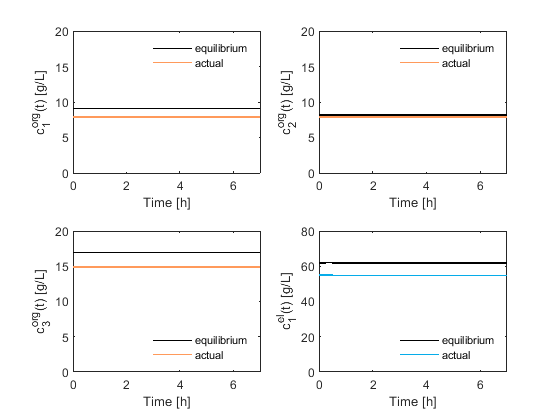

% Create the group of equilibrium concentrations
figure()

% Plot C1_org equilibrium
subplot(2,2,1)
plot(model_time, simulation_results.C1_org_eq.Data, 'k-', 'LineWidth', 1)
hold on
plot(model_time, simulation_results.C1_org.Data, 'LineWidth', 1 ,'Color', orange)
hold off
legend('equilibrium', 'actual')
legend('boxoff')
ylabel("c_{1}^{org}(t) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C2_org equilibrium
subplot(2,2,2)
plot(model_time, simulation_results.C2_org_eq.Data, 'k-', 'LineWidth', 1)
hold on
plot(model_time, simulation_results.C2_org.Data, 'LineWidth', 1 ,'Color', orange)
hold off
legend('equilibrium', 'actual')
legend('boxoff')
ylabel("c_{2}^{org}(t) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C3_org equilibrium
subplot(2,2,3)
plot(model_time, simulation_results.C3_org_eq.Data, 'k-', 'LineWidth', 1)
hold on
plot(model_time, simulation_results.C3_org.Data, 'LineWidth', 1 ,'Color', orange)
hold off
legend({'equilibrium', 'actual'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{3}^{org}(t) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot C1_el equilibrium
subplot(2,2,4)
plot(model_time, simulation_results.C1_el_eq.Data, 'k-', 'LineWidth', 1)
hold on
plot(model_time, simulation_results.C1_el.Data, 'LineWidth', 1 ,'Color', blue)
hold off
legend({'equilibrium', 'actual'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{1}^{el}(t) [g/L]")
xlabel("Time [h]")
ylim([0 80])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/process_variables/equilibrium_concentrations', '-dpng', '-r600')

### Plot the aqueous concentrations

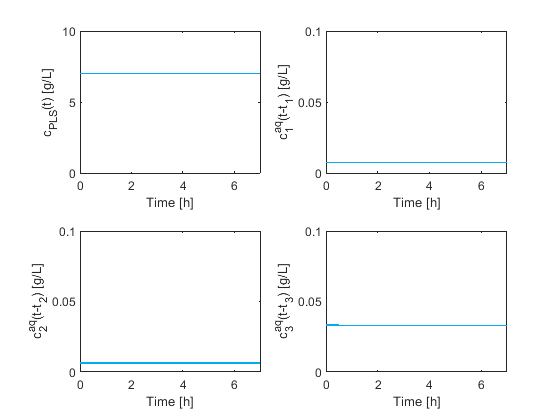

% Create the group of aqueous concentrations
figure()

% Plot cPLS
subplot(2,2,1)
plot(model_time, simulation_results.cPLS.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("c_{PLS}(t) [g/L]")
xlabel("Time [h]")
ylim([0 10])
xlim([0 model_time(end)])

% Plot C1_aq_delay
subplot(2,2,2)
plot(model_time, simulation_results.C1_aq_delay.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("c_{1}^{aq}(t-t_{1}) [g/L]")
xlabel("Time [h]")
ylim([0 0.1])
xlim([0 model_time(end)])

% Plot C2_aq_delay
subplot(2,2,3)
plot(model_time, simulation_results.C2_aq_delay.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("c_{2}^{aq}(t-t_{2}) [g/L]")
xlabel("Time [h]")
ylim([0 0.1])
xlim([0 model_time(end)])

% Plot C3_aq_delay
subplot(2,2,4)
plot(model_time, simulation_results.C3_aq_delay.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("c_{3}^{aq}(t-t_{3}) [g/L]")
xlabel("Time [h]")
ylim([0 0.1])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/process_variables/aqueous_concentrations', '-dpng', '-r600')

### Plot the electrolyte concentrations

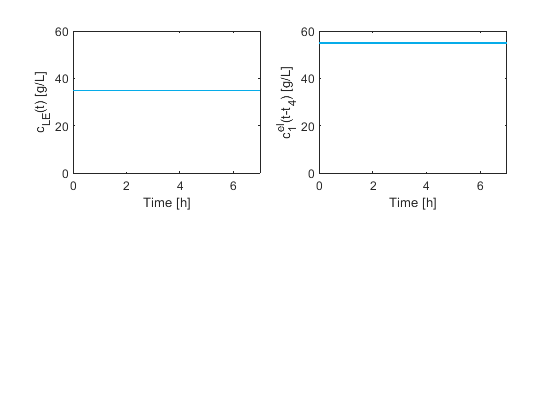

% Create the group of electrolyte concentrations
figure()

% Plot cLE
subplot(2,2,1)
plot(model_time, simulation_results.cLE.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("c_{LE}(t) [g/L]")
xlabel("Time [h]")
ylim([0 60])
xlim([0 model_time(end)])

% Plot C1_el_delay
subplot(2,2,2)
plot(model_time, simulation_results.C1_el_delay.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("c_{1}^{el}(t-t_{4}) [g/L]")
xlabel("Time [h]")
ylim([0 60])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/process_variables/electrolyte_concentrations', '-dpng', '-r600')

### Plot the flowrates

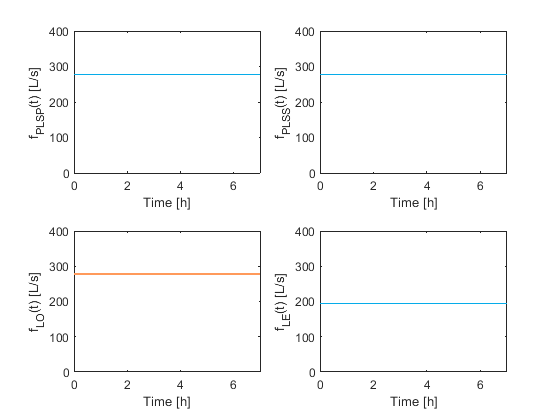

% Create the group of flowrates
figure()

% Plot fPLSP
subplot(2,2,1)
plot(model_time, simulation_results.fPLSP.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("f_{PLSP}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot fPLSS
subplot(2,2,2)
plot(model_time, simulation_results.fPLSS.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("f_{PLSS}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot fLO
subplot(2,2,3)
plot(model_time, simulation_results.fLO.Data, 'LineWidth', 1 ,'Color', orange)
ylabel("f_{LO}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot fLE
subplot(2,2,4)
plot(model_time, simulation_results.fLE.Data, 'LineWidth', 1 ,'Color', blue)
ylabel("f_{LE}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/process_variables/flowrates', '-dpng', '-r600')

### Plot the valve positions

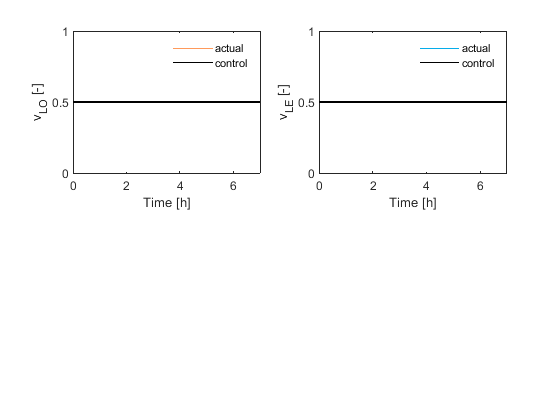

% Create the group of valve positions
figure()

% Plot vLO
subplot(2,2,1)
plot(model_time, simulation_results.vLO_valve.Data, 'LineWidth', 1 ,'Color', orange)
hold on
plot(model_time, simulation_results.vLO_control.Data, 'k-', 'LineWidth', 1)
hold off
legend('actual', 'control')
legend('boxoff')
ylabel("v_{LO} [-]")
xlabel("Time [h]")
ylim([0 1])
xlim([0 model_time(end)])

% Plot vLE
subplot(2,2,2)
plot(model_time, simulation_results.vLE_valve.Data, 'LineWidth', 1 ,'Color', blue)
hold on
plot(model_time, simulation_results.vLE_control.Data, 'k-', 'LineWidth', 1)
hold off
legend('actual', 'control')
legend('boxoff')
ylabel("v_{LE} [-]")
xlabel("Time [h]")
ylim([0 1])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/process_variables/valve_positions', '-dpng', '-r600')

## Plot the sensor noise

### Plot the flowrate sensor noise

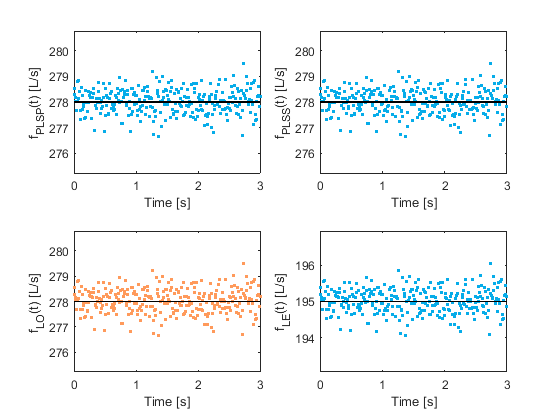

% Create the group of measured flowrates
figure()

% Plot f_PLSP_measured
subplot(2,2,1)
plot(simulation_results.tout, simulation_results.f_PLSP_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
hold on
plot(simulation_results.tout, simulation_results.fPLSP.Data, '-k', 'LineWidth', 1)
hold off
ylabel("f_{PLSP}(t) [L/s]")
xlabel("Time [s]")
ylim([fPLSP_ss*(0.99) fPLSP_ss*(1.01)])
xlim([0 3])

% Plot f_PLSS_measured
subplot(2,2,2)
plot(simulation_results.tout, simulation_results.f_PLSS_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
hold on
plot(simulation_results.tout, simulation_results.fPLSS.Data, '-k', 'LineWidth', 1)
hold off
ylabel("f_{PLSS}(t) [L/s]")
xlabel("Time [s]")
ylim([fPLSS_ss*(0.99) fPLSS_ss*(1.01)])
xlim([0 3])

% Plot f_LO_measured
subplot(2,2,3)
plot(simulation_results.tout, simulation_results.f_LO_measured.Data, '.', 'MarkerSize', 6 ,'Color', orange)
hold on
plot(simulation_results.tout, simulation_results.fLO.Data, '-k', 'LineWidth', 1)
hold off
ylabel("f_{LO}(t) [L/s]")
xlabel("Time [s]")
ylim([fLO_max*vLO_ss*(0.99) fLO_max*vLO_ss*(1.01)])
xlim([0 3])

% Plot f_LE_measured
subplot(2,2,4)
plot(simulation_results.tout, simulation_results.f_LE_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
hold on
plot(simulation_results.tout, simulation_results.fLE.Data, '-k', 'LineWidth', 1)
hold off
ylabel("f_{LE}(t) [L/s]")
xlabel("Time [s]")
ylim([fLE_max*vLE_ss*(0.99) fLE_max*vLE_ss*(1.01)])
xlim([0 3])

% Save the current figure
print('output/process_model/graphs/sensor_noise/flowrates_sensor_noise', '-dpng', '-r600')

### Plot the PLS concentrations sensor noise

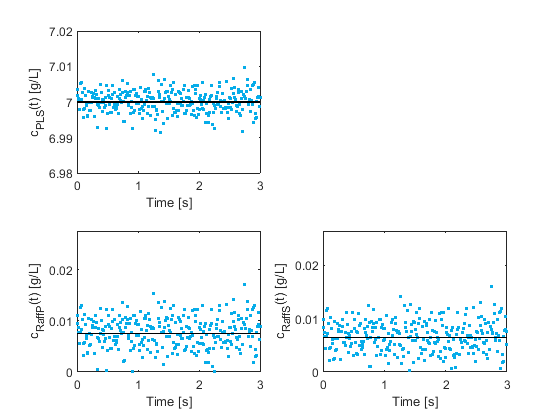

% Create the group of measured PLS concentrations
figure()

% Plot c_PLS_measured
subplot(2,2,1)
plot(simulation_results.tout, simulation_results.c_PLS_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
hold on
plot(simulation_results.tout, simulation_results.cPLS.Data, '-k', 'LineWidth', 1)
hold off
ylabel("c_{PLS}(t) [g/L]")
xlabel("Time [s]")
ylim([(cPLS_ss-0.02) (cPLS_ss+0.02)])
xlim([0 3])

% Plot c_RaffP_measured
subplot(2,2,3)
plot(simulation_results.tout, simulation_results.c_RaffP_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
hold on
plot(simulation_results.tout, simulation_results.C1_aq_delay.Data, '-k', 'LineWidth', 1)
hold off
ylabel("c_{RaffP}(t) [g/L]")
xlabel("Time [s]")
ylim([0 (C1_aq_ss+0.02)])
xlim([0 3])

% Plot c_RaffS_measured
subplot(2,2,4)
plot(simulation_results.tout, simulation_results.c_RaffS_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
hold on
plot(simulation_results.tout, simulation_results.C2_aq_delay.Data, '-k', 'LineWidth', 1)
hold off
ylabel("c_{RaffS}(t) [g/L]")
xlabel("Time [s]")
ylim([0 (C2_aq_ss+0.02)])
xlim([0 3])

% Save the current figure
print('output/process_model/graphs/sensor_noise/PLS_concentrations_sensor_noise', '-dpng', '-r600')

## Plot the measured variables

### Plot the measured flowrates

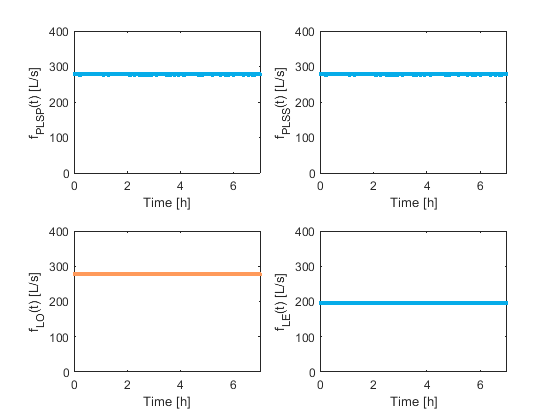

% Create the group of measured flowrates
figure()

% Plot f_PLSP_measured
subplot(2,2,1)
plot(model_time, simulation_results.f_PLSP_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("f_{PLSP}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot f_PLSS_measured
subplot(2,2,2)
plot(model_time, simulation_results.f_PLSS_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("f_{PLSS}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot f_LO_measured
subplot(2,2,3)
plot(model_time, simulation_results.f_LO_measured.Data, '.', 'MarkerSize', 6 ,'Color', orange)
ylabel("f_{LO}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Plot f_LE_measured
subplot(2,2,4)
plot(model_time, simulation_results.f_LE_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("f_{LE}(t) [L/s]")
xlabel("Time [h]")
ylim([0 400])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/measured_variables/measured_flowrates', '-dpng', '-r600')

### Plot the measured PLS concentrations

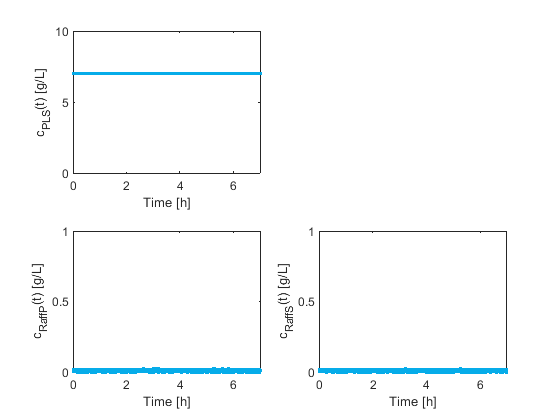

% Create the group of measured PLS concentrations
figure()

% Plot c_PLS_measured
subplot(2,2,1)
plot(model_time, simulation_results.c_PLS_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("c_{PLS}(t) [g/L]")
xlabel("Time [h]")
ylim([0 10])
xlim([0 model_time(end)])

% Plot c_RaffP_measured
subplot(2,2,3)
plot(model_time, simulation_results.c_RaffP_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("c_{RaffP}(t) [g/L]")
xlabel("Time [h]")
ylim([0 1])
xlim([0 model_time(end)])

% Plot c_RaffS_measured
subplot(2,2,4)
plot(model_time, simulation_results.c_RaffS_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("c_{RaffS}(t) [g/L]")
xlabel("Time [h]")
ylim([0 1])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/measured_variables/measured_PLS_concentrations', '-dpng', '-r600')

### Plot the measured organic concentrations

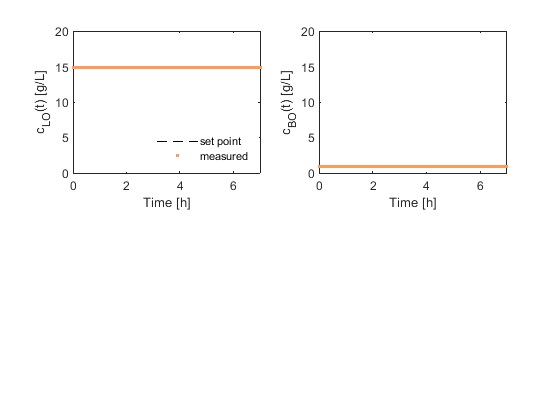

% Create the group of measured organic concentrations
figure()

% Plot c_LO_measured
subplot(2,2,1)
plot(model_time, simulation_results.cLO_SP.Data, 'k--', 'LineWidth', 1)
hold on
plot(model_time, simulation_results.c_LO_measured.Data, '.', 'MarkerSize', 6 ,'Color', orange)
hold off
legend({'set point','measured'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{LO}(t) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Plot c_BO_measured
subplot(2,2,2)
plot(model_time, simulation_results.c_BO_measured.Data, '.', 'MarkerSize', 6 ,'Color', orange)
ylabel("c_{BO}(t) [g/L]")
xlabel("Time [h]")
ylim([0 20])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/measured_variables/measured_organic_concentrations', '-dpng', '-r600')

### Plot the measured electrolyte concentrations

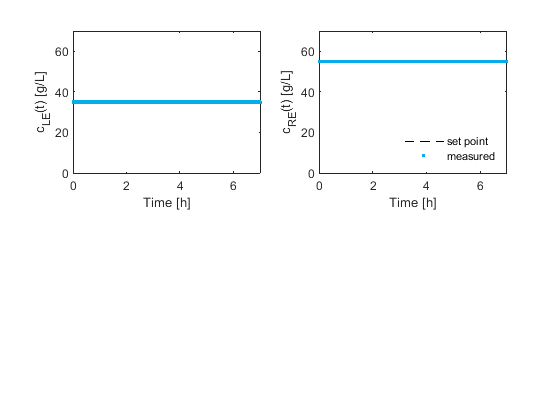

% Create the group of measured electrolyte variables
figure()

% Plot c_LE_measured
subplot(2,2,1)
plot(model_time, simulation_results.c_LE_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
ylabel("c_{LE}(t) [g/L]")
xlabel("Time [h]")
ylim([0 70])
xlim([0 model_time(end)])

% Plot c_RE_measured
subplot(2,2,2)
plot(model_time, simulation_results.cRE_SP.Data, 'k--', 'LineWidth', 1)
hold on
plot(model_time, simulation_results.c_RE_measured.Data, '.', 'MarkerSize', 6 ,'Color', blue)
hold off
legend({'set point','measured'}, 'Location', 'southeast')
legend('boxoff')
ylabel("c_{RE}(t) [g/L]")
xlabel("Time [h]")
ylim([0 70])
xlim([0 model_time(end)])

% Save the current figure
print('output/process_model/graphs/measured_variables/measured_electrolyte_concentrations', '-dpng', '-r600')

## Save the Measured Sensor data to a CSV file

### Write the data to a table

% Create a blank table
MEASURED_DATA = table();

% Add the simulation time
MEASURED_DATA.Time = simulation_results.tout;

% Add the controlled variables
MEASURED_DATA.c_LO_measured = round(simulation_results.c_LO_measured.Data, 2, 'decimals');
MEASURED_DATA.c_RE_measured = round(simulation_results.c_RE_measured.Data, 2, 'decimals');

% Add the flowrates
MEASURED_DATA.f_PLSP_measured = round(simulation_results.f_PLSP_measured.Data, 2, 'decimals');
MEASURED_DATA.f_PLSS_measured = round(simulation_results.f_PLSS_measured.Data, 2, 'decimals');
MEASURED_DATA.f_LO_measured   = round(simulation_results.f_LO_measured.Data, 2, 'decimals');
MEASURED_DATA.f_LE_measured   = round(simulation_results.f_LE_measured.Data, 2, 'decimals');

% Add the concentrations
MEASURED_DATA.c_PLS_measured   = round(simulation_results.c_PLS_measured.Data, 2, 'decimals');
MEASURED_DATA.c_LE_measured    = round(simulation_results.c_LE_measured.Data, 2, 'decimals');
MEASURED_DATA.c_RaffP_measured = round(simulation_results.c_RaffP_measured.Data, 2, 'decimals');
MEASURED_DATA.c_RaffS_measured = round(simulation_results.c_RaffS_measured.Data, 2, 'decimals');
MEASURED_DATA.c_BO_measured    = round(simulation_results.c_BO_measured.Data, 2, 'decimals');

% View the Table
MEASURED_DATA

MEASURED_DATA = 2520001×12 table
    Time    c_LO_measured    c_RE_measured    f_PLSP_measured    f_PLSS_measured    f_LO_measured    f_LE_measured    c_PLS_measured    c_LE_measured    c_RaffP_measured    c_RaffS_measured    c_BO_measured
    ____    _____________    _____________    _______________    _______________    _____________    _____________    ______________    _____________    ________________    ________________    _____________

       0        14.88            54.96            278.55             278.55            278.55           195.38                7                3

### Save the table to a CSV file

writetable(MEASURED_DATA, "output/process_model/data/measured_data.csv");